# 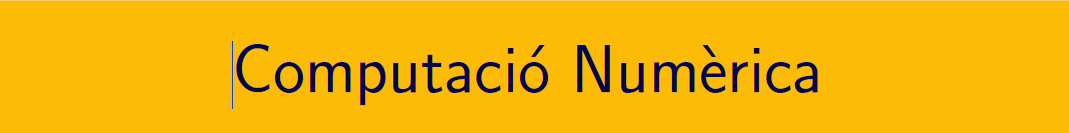

`===================================================================================`

# Pràctica 14. Equacions diferencials ordinàries (IV).

`Document preparat per M. Àngela Grau Gotés - 29 de maig de 2023`

## `Sistemes d'equacions diferencials de primer ordre`

## `Exercici  `


$$	\left\lbrace \begin{array}{rcl}
			u_1^{\prime}(t)&=&9u_1(t)+24u_2(t)+5\cos(t)-\frac13\sin(t)\,, 			\\  u_2^{\prime}(t)&=&-24u_1(t)-51u_2(t)-9\cos(t)+\frac13\sin(t)\,,\,, \\
u_1(0) &=& \frac43\,,\\
u_2(0) &=& \frac23\,.
\end{array}\right. $$


`Solució analítica`

clearvars
syms y(t) z(t)
eqns = [diff(y,t) == 9*y+24*z+5*cos(t)-sin(t)/3, diff(z,t) == -24*y-51*z-9*cos(t)+sin(t)/3];
conds = [y(0) == 4/3, z(0)==2/3];
[ySol(t),zSol(t)] = dsolve(eqns,conds);

`La solució es pot respresentar a l'interval [0,1]`

Y(t) = simplify(ySol(t)),Z(t) = simplify(zSol(t))

$$Y(t) = 2\,{\mathrm{e}}^{-3\,t}-{\mathrm{e}}^{-39\,t}+\frac{\cos\left(t\right)}{3}$$

$$Z(t) = 2\,{\mathrm{e}}^{-39\,t}-{\mathrm{e}}^{-3\,t}-\frac{\cos\left(t\right)}{3}$$

## `Solucions aproximades numèricament O(h^2)`

- `Mètode ode23`

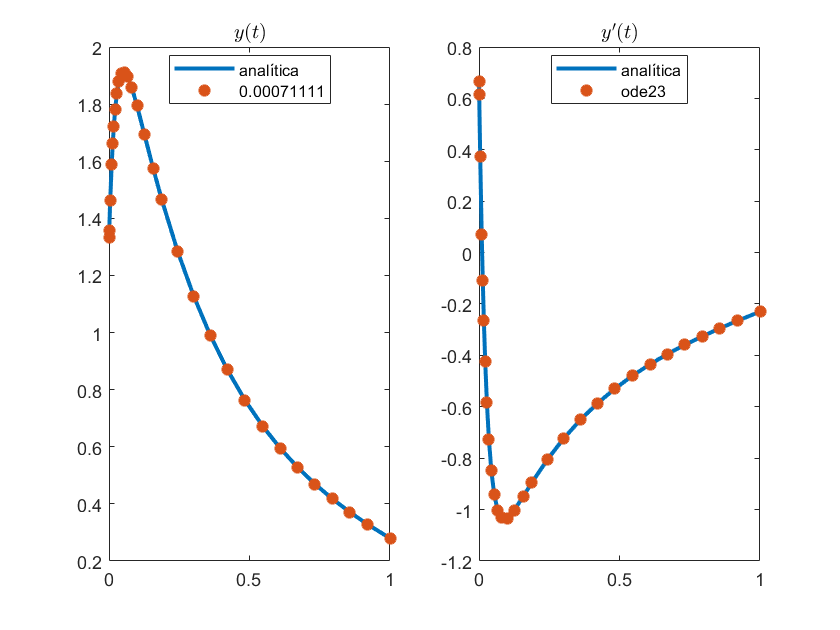

 [t,y] = ode23(@edos,[0 1],[4/3; 2/3]);
 
 % Gràfics
clf,figure(1)
subplot(121),plot(t,Y(t),t,y(:,1),'*','LineWidth',2)
title('$y(t)$','Interpreter','latex')
legend('analítica',num2str(t(2)-t(1)),'Location','best')
subplot(122),plot(t,Z(t),t,y(:,2),'*','LineWidth',2)
title('$y^\prime(t)$','Interpreter','latex')
legend('analítica','ode23','Location','best')
hold off

## `Solucions aproximades numèricament O(h)`

- `Mètode Euler (sistemes equacions)`

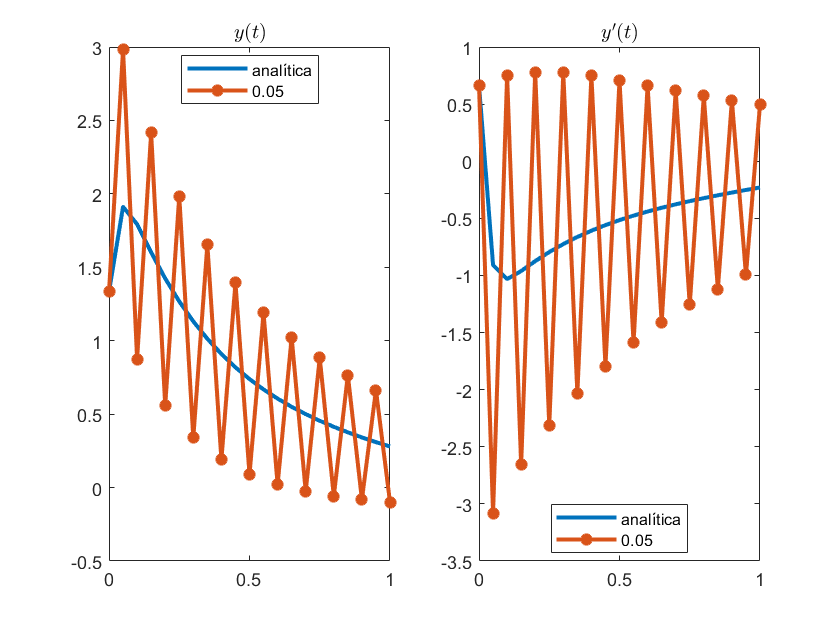

[t,YE] = EulerV(@edos,0,1,0.05,[4/3; 2/3]);
 
figure(2)
subplot(121),plot(t,Y(t),t,YE(:,1),'*-','LineWidth',2)
title('$y(t)$','Interpreter','latex')
legend('analítica',num2str(t(2)-t(1)),'Location','best')
subplot(122),plot(t,Z(t),t,YE(:,2),'*-','LineWidth',2)
title('$y^\prime(t)$','Interpreter','latex')
legend('analítica',num2str(t(2)-t(1)),'Location','best')
hold off

function dydt = edos(t,y)
% 
    dydt = [9*y(1)+24*y(2)+5*cos(t)-sin(t)/3; -24*y(1)-51*y(2)-9*cos(t)+sin(t)/3];
end
%---------------------------------------
function [t, w ] = EulerV( f,a,b,h,alpha )
% Mètode d'Euler
% f una funcion @algo que retorna un vector columna [y1; y2; ...]
t=[a:h:b];
N=length(t);
w(1,:)=alpha;
    for i=1:N-1
        w(i+1,:)=w(i,:)+h*f(t(i),w(i,:))';
    end
end
%%%%